##  Задание 2. Наблюдатель полного порядка.  

Начальные условия на задание:

A = [-40 16 9 -7;
 -64 25 14 -12;
 -26 11 7 -3;
 48 -18 -14 8]

A =    -40    16     9    -7
   -64    25    14   -12
   -26    11     7    -3
    48   -18   -14     8



C = [-7, -2, 5, -3]

C =     -7    -2     5    -3



lambda = [-4,-4,-4,-4]

lambda =     -4    -4    -4    -4


lambda = [-4,-40,-400,-4000]

lambda =           -4         -40        -400       -4000


lambda = [-4+5i,-4+5i,-4+6i-4-6i]

lambda =   -4.0000 + 5.0000i  -4.0000 + 5.0000i  -8.0000 + 0.0000i


Найти собственные числа матрицы A и определить управляемость каждого из них. Сделать вывод об управляемости и стабилизируемости системы.

V = obsv(A,C)

V =           -7          -2           5          -3
         134         -53         -14          34
          28          53        -110          12
       -1076         347          56        -406


V = [C ; C*A ; C * A^2 ; C * A^3]

V =           -7          -2           5          -3
         134         -53         -14          34
          28          53        -110          12
       -1076         347          56        -406


rank(V)

ans = 4

Проверка критерия Хаутуса:

eig(A)

ans =    0.0000 + 3.0000i
   0.0000 - 3.0000i
   0.0000 + 2.0000i
   0.0000 - 2.0000i


l1 = + 3j; l2 = - 3j; l3 = -2j;l4 = +2j; 

vpa([A - eye(4).*l1 ; C])

$$ans = \left(\begin{array}{cccc} -40.0-3.0\,\mathrm{i} & 16.0 & 9.0 & -7.0\\ -64.0 & 25.0-3.0\,\mathrm{i} & 14.0 & -12.0\\ -26.0 & 11.0 & 7.0-3.0\,\mathrm{i} & -3.0\\ 48.0 & -18.0 & -14.0 & 8.0-3.0\,\mathrm{i}\\ -7.0 & -2.0 & 5.0 & -3.0 \end{array}\right)$$

vpa([A - eye(4).*l2 ; C])

$$ans = \left(\begin{array}{cccc} -40.0+3.0\,\mathrm{i} & 16.0 & 9.0 & -7.0\\ -64.0 & 25.0+3.0\,\mathrm{i} & 14.0 & -12.0\\ -26.0 & 11.0 & 7.0+3.0\,\mathrm{i} & -3.0\\ 48.0 & -18.0 & -14.0 & 8.0+3.0\,\mathrm{i}\\ -7.0 & -2.0 & 5.0 & -3.0 \end{array}\right)$$

vpa([A - eye(4).*l3 ; C])

$$ans = \left(\begin{array}{cccc} -40.0+2.0\,\mathrm{i} & 16.0 & 9.0 & -7.0\\ -64.0 & 25.0+2.0\,\mathrm{i} & 14.0 & -12.0\\ -26.0 & 11.0 & 7.0+2.0\,\mathrm{i} & -3.0\\ 48.0 & -18.0 & -14.0 & 8.0+2.0\,\mathrm{i}\\ -7.0 & -2.0 & 5.0 & -3.0 \end{array}\right)$$

vpa([A - eye(4).*l4 ; C])

$$ans = \left(\begin{array}{cccc} -40.0-2.0\,\mathrm{i} & 16.0 & 9.0 & -7.0\\ -64.0 & 25.0-2.0\,\mathrm{i} & 14.0 & -12.0\\ -26.0 & 11.0 & 7.0-2.0\,\mathrm{i} & -3.0\\ 48.0 & -18.0 & -14.0 & 8.0-2.0\,\mathrm{i}\\ -7.0 & -2.0 & 5.0 & -3.0 \end{array}\right)$$



rank([A - eye(4).*l1 ; C])

ans = 4

rank([A - eye(4).*l2 ; C])

ans = 4

rank([A - eye(4).*l3 ; C])

ans = 4

rank([A - eye(4).*l4 ; C])

ans = 4

**A --> Наблюдаема + обнаруживаема значит**

Для каждого спектра...

lambda = [-4,-4,-4,-4]

lambda =     -4    -4    -4    -4




[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =    -1.1422    0.0544   -1.1314   -0.1414
   -1.7406    0.2176   -1.8385   -0.1414
   -0.8703    0.1088   -0.7071         0
    1.4142         0    1.4142         0


double(Aj2)

ans =      0    -2     0     0
     2     0     0     0
     0     0     0    -3
     0     0     3     0



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

G = [-4 1 0 0;
      0 -4 1 0;
      0   0  -4 1;
      0    0   0 -4]

G =     -4     1     0     0
     0    -4     1     0
     0     0    -4     1
     0     0     0    -4


Y = [0 1 0 1]'

Y =      0
     1
     0
     1




Q = sylvester(G, -A, Y*C);
L = pinv(Q) * Y

L =    11.0838
   16.9940
    9.7415
  -15.6224


eig(A + L*C)

ans =   -4.0033 + 0.0033i
  -4.0033 - 0.0033i
  -3.9967 + 0.0033i
  -3.9967 - 0.0033i



%%%%%%%%%%%%%%%% - nice
cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e-01|4.2e+03|7.6e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.978|8.6e-05|9.3e+01|3.8e+03| 0.000000e+00  3.004756e+01| 0:0:00| chol  1  1 
 2|1.000|0.989|3.2e-05|1.0e+00|1.3e+01| 0.000000e+00  3.477960e-01| 0:0:00| chol  1  1 
 3|1.000|0.989|3.8e-07|1.2e-02|8.3e-02| 0.000000e+00  7.024533e-03| 0:0:00| chol  1  1 
 4|1.000|0.98

L = pinv(Q)*Y

L =    11.0838
   16.9940
    9.7415
  -15.6224


eig(A+L*C)

ans =   -4.0044 + 0.0000i
  -4.0000 + 0.0044i
  -4.0000 - 0.0044i
  -3.9956 + 0.0000i


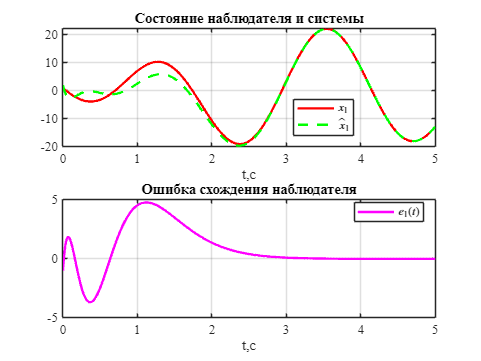

%%%%%%%%%%%%%%%%
x0 = [1 1 1 1]';        % plant
x_hat0 = [2 0 0 -1]';   % observer
D = 0;


simTimeStart = 0;
simTimeEnd = 5;
step = 0.0001; 
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("obsv1");

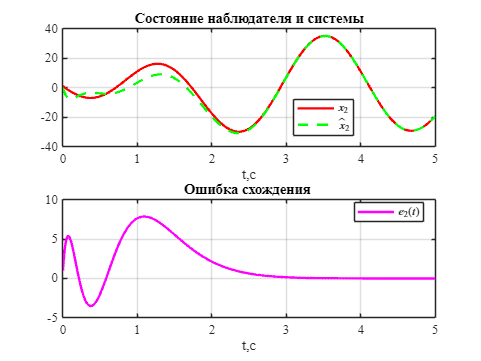

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("obsv2");

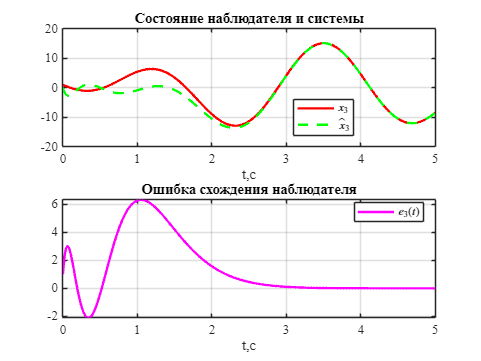

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("obsv3");

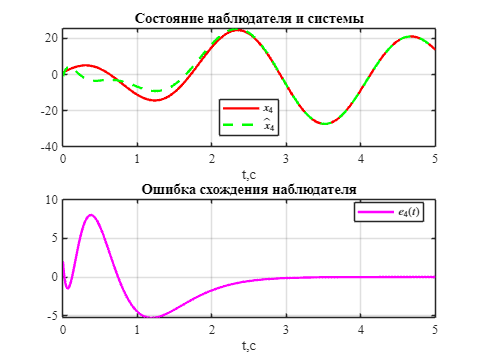

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("obsv4");

%%%%%%%%%%%%%%

Второй спектр

lambda = [-4,-40,-400,-4000]

lambda =           -4         -40        -400       -4000



[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =    -1.1422    0.0544   -1.1314   -0.1414
   -1.7406    0.2176   -1.8385   -0.1414
   -0.8703    0.1088   -0.7071         0
    1.4142         0    1.4142         0


double(Aj2)

ans =      0    -2     0     0
     2     0     0     0
     0     0     0    -3
     0     0     3     0



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

G = diag(lambda)

G =           -4           0           0           0
           0         -40           0           0
           0           0        -400           0
           0           0           0       -4000


Y = [1 1 1 1]'

Y =      1
     1
     1
     1




Q = sylvester(G, -A, Y*C);
L = pinv(Q) * Y

L = 1.0e+06 *

    0.3157
    0.9717
    1.2754
    0.7427


eig(A + L*C)

ans = 1.0e+03 *

   -4.0000
   -0.4000
   -0.0400
   -0.0040



%%%%%%%%%%%%%%%% - nice
cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 12 variables, 12 equality constraints
------------------------------------------------------------

 num. of constraints = 12
 dim. of linear var  =  1
 dim. of free   var  = 12 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.4e-01|1.4e+05|1.6e+07| 0.000000e+00  0.000000e+00| 0:0:00| chol  1  1 
 1|1.000|0.975|7.0e-05|3.4e+03|8.8e+04| 0.000000e+00  7.070633e+02| 0:0:00| chol  1  1 
 2|1.000|0.989|1.6e-05|3.8e+01|2.7e+02| 0.000000e+00  7.894388e+00| 0:0:00| chol  1  1 
 3|1.000|0.989|1.8e-07|4.3e-01|2.1e+00| 0.000000e+00  1.015113e-01| 0:0:00| chol  1  1 
 4|1.000|0.98

L = pinv(Q)*Y

L = 1.0e+06 *

    0.3157
    0.9717
    1.2754
    0.7427


eig(A+L*C)

ans = 1.0e+03 *

   -4.0000
   -0.4000
   -0.0400
   -0.0040


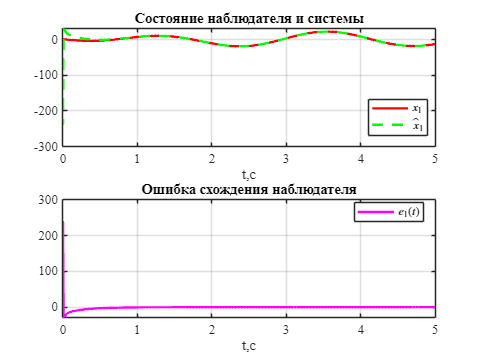

%%%%%%%%%%%%%%%%
x0 = [1 1 1 1]';        % plant
x_hat0 = [2 0 0 -1]';   % observer
D = 0;


simTimeStart = 0;
simTimeEnd = 5;
step = 0.00005;
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("obsv5");

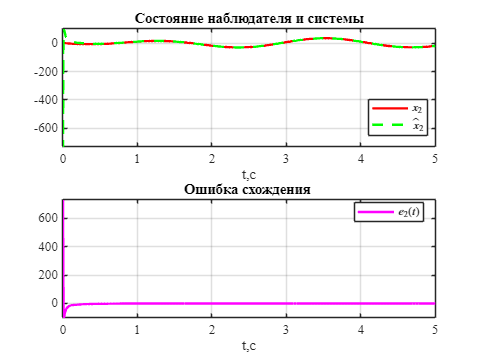

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("obsv6");

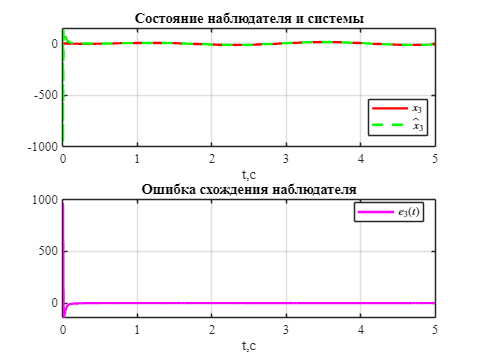

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("obsv7");

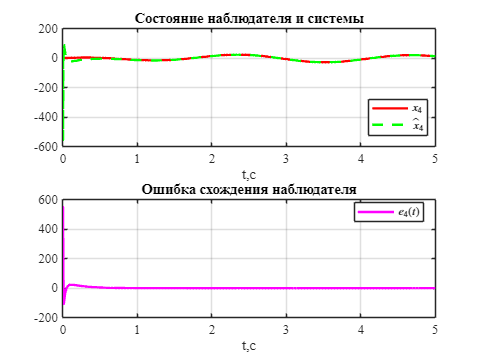

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("obsv8");

%%%%%%%%%%%%%%

Третий

lambda = [-4+5i,-4+5i,-4+6i-4-6i]

lambda =   -4.0000 + 5.0000i  -4.0000 + 5.0000i  -8.0000 + 0.0000i



[P,Aj] = jordan(A);
[P2, Aj2] = cdf2rdf(P,Aj);
double(P2)

ans =    -1.1422    0.0544   -1.1314   -0.1414
   -1.7406    0.2176   -1.8385   -0.1414
   -0.8703    0.1088   -0.7071         0
    1.4142         0    1.4142         0


double(Aj2)

ans =      0    -2     0     0
     2     0     0     0
     0     0     0    -3
     0     0     3     0



P1(:,1)=real(P(:,1)); 
P1(:,2)=imag(P(:,2)); 
P1(:,3)=real(P(:,3)); 

G = [-4   5   0  0;
      -5  -4  0  0;
      0   0  -4  6;
      0   0   -6 -4]

G =     -4     5     0     0
    -5    -4     0     0
     0     0    -4     6
     0     0    -6    -4


eig(G)

ans =   -4.0000 + 5.0000i
  -4.0000 - 5.0000i
  -4.0000 + 6.0000i
  -4.0000 - 6.0000i



Y = [0 1 0 1]'

Y =      0
     1
     0
     1




Q = sylvester(G, -A, Y*C);
L = pinv(Q) * Y

L =    14.5661
   25.8784
   19.6058
  -13.2300


eig(A + L*C)

ans =   -4.0000 + 6.0000i
  -4.0000 - 6.0000i
  -4.0000 + 5.0000i
  -4.0000 - 5.0000i



%%%%%%%%%%%%%%%% - nice
cvx_begin sdp
variable Q(4,4)
G * Q - Q * A == Y*C;
cvx_end

 
Calling SDPT3 4.0: 16 variables, 16 equality constraints
------------------------------------------------------------

 num. of constraints = 16
 dim. of linear var  =  1
 dim. of free   var  = 16 *** convert ublk to lblk
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|9.3e-01|4.2e+03|7.6e+05| 0.000000e+00  0.000000e+00| 0:0:00| chol  2  2 
 1|1.000|0.983|3.6e-06|6.9e+01|2.7e+03| 0.000000e+00  1.609910e+00| 0:0:00| chol  1  1 
 2|1.000|0.989|7.2e-06|7.7e-01|7.8e+00| 0.000000e+00  2.189200e-02| 0:0:00| chol  1  1 
 3|1.000|0.990|1.4e-07|9.0e-03|4.1e-02| 0.000000e+00  1.432129e-03| 0:0:00| chol  1  1 
 4|1.000|0.99

L = pinv(Q)*Y

L =    14.5661
   25.8784
   19.6058
  -13.2300


eig(A+L*C)

ans =   -4.0000 + 6.0000i
  -4.0000 - 6.0000i
  -4.0000 + 5.0000i
  -4.0000 - 5.0000i


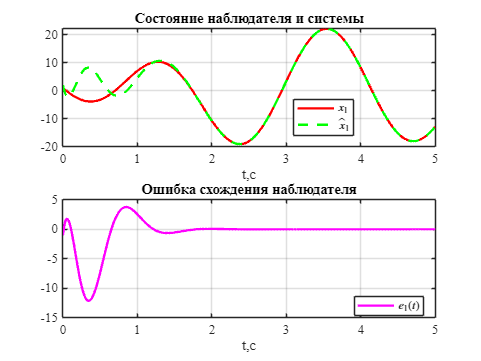

%%%%%%%%%%%%%%%%
x0 = [1 1 1 1]';        % plant
x_hat0 = [2 0 0 -1]';   % observer
D = 0;


simTimeStart = 0;
simTimeEnd = 5;
step = 0.00005;
time = (simTimeStart:step:simTimeEnd)';

data.time= time;
modelName = 'model_observer'; 
load_system(modelName);
out = sim(modelName, 'StopTime', num2str(simTimeEnd), 'FixedStep',num2str(step));

time = out.y_plant.Time;                
x_plant = out.x_plant.Data;
x_obsv = out.x_obsv.Data;
error = out.out_error.Data;

h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,1), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,1),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{1}$','$\hat{x}_{1}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,1),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_1(t)$','Location','best','Interpreter','latex') 
save_file("obsv9");

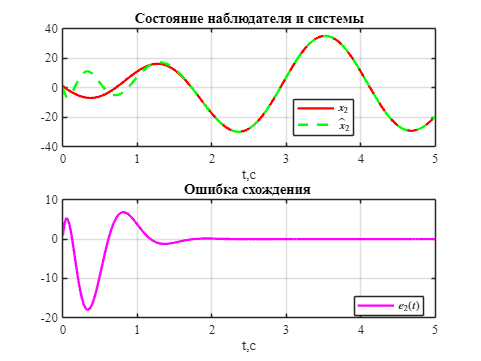

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,2), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,2),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{2}$','$\hat{x}_{2}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,2),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения ')
xlabel('t,c'); ylabel(' ') ;
legend('$e_2(t)$','Location','best','Interpreter','latex') 
save_file("obsv10");

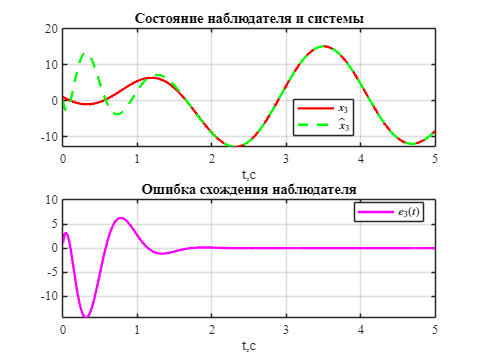

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,3), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,3),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{3}$','$\hat{x}_{3}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,3),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_3(t)$','Location','best','Interpreter','latex') 
save_file("obsv11");

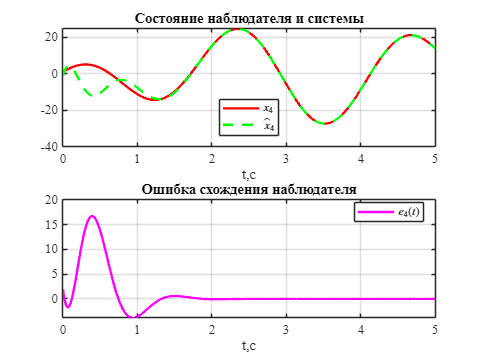

%%%%%%%%%%%%%%
h = figure; 
set(h,'DefaultAxesFontSize', 12, 'DefaultAxesFontName','Times New Roman');
% OBSV vs PLANT
subplot(2,1,1) 
plot(time, x_plant(:,4), 'r', 'LineWidth',2); hold on ;
plot(time, x_obsv(:,4),'g','LineWidth',2,'LineStyle','--'); grid on ;
xlabel('t,c'); ylabel(' ');
title('Состояние наблюдателя и системы')
legend('$x_{4}$','$\hat{x}_{4}$','Interpreter','latex','Location','best') 
% ERROR
subplot(2,1,2) 
plot(time, error(:,4),'magenta', 'LineWidth',2); grid on;
title('Ошибка схождения наблюдателя')
xlabel('t,c'); ylabel(' ') ;
legend('$e_4(t)$','Location','best','Interpreter','latex') 
save_file("obsv12");

%%%%%%%%%%%%%%

**Функция, чтобы сохранить картинку в папку**

function save_file(name)
    path = 'D:\Math\control_theory\control_theory_labs\lab8\latex8\images';
    fullpath = fullfile(path, name);
    saveas(gcf, fullpath, 'png');

end